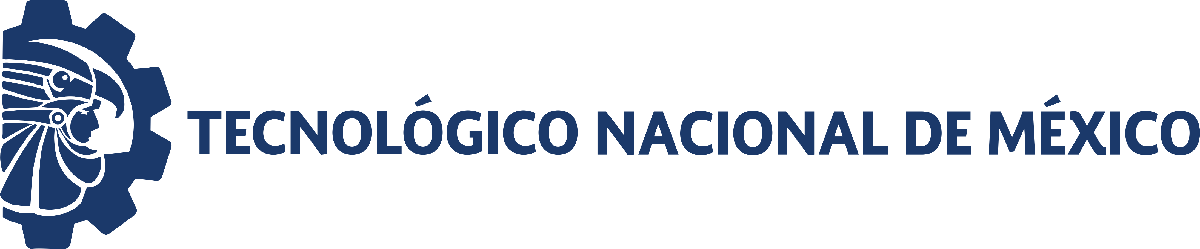                                 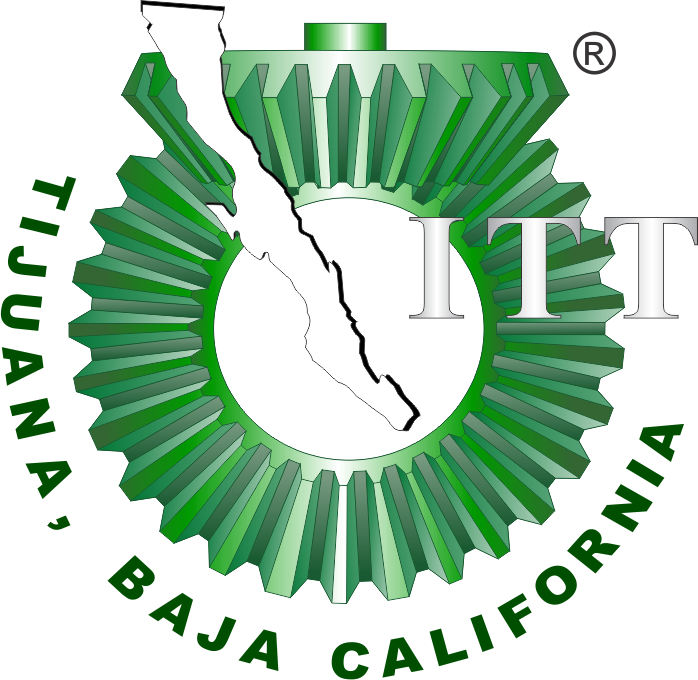

# Proyecto

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre de los alumnos: 

**Cobos Mejia Jesus Antonio**

**Cesar Gonzalez Sebastian**

**Fernandez Lira Luis Abdiel**

Números de control: 

**21212146**

**21212148**

**21212154**

Correos institucionales: 

l**21212146@tectijuana.edu.mx**

l**21212148@tectijuana.edu.mx**

l**21212154@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='Sistema5';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode45';
parameters.MaxStep='1E-3';



## Se**ñ**al cardiaca

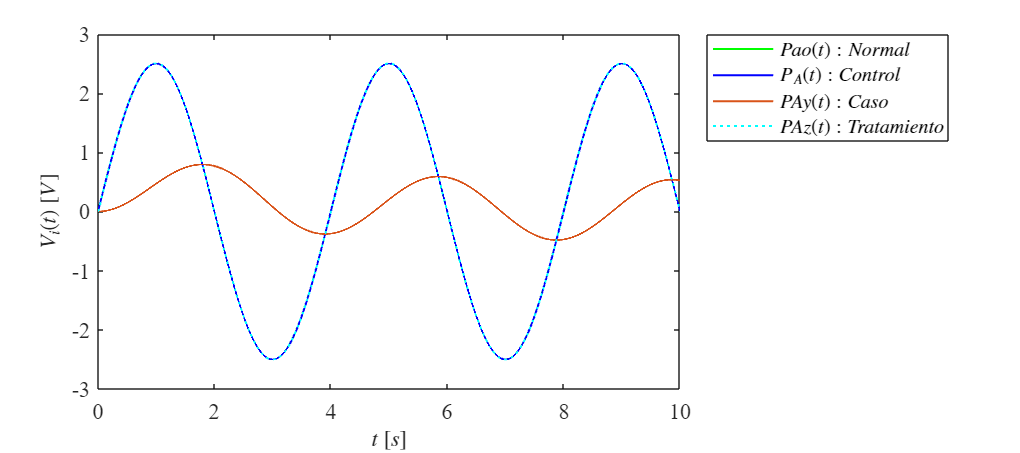

Signal='InsuficienciaCardiaca';
x1=sim(file,parameters);
plotsignals(x1.tout,x1.Pao,x1.PAx,x1.PAy,x1.PAz,Signal)

## **Funciones**

function plotsignals(t,Pao,PAx,PAy,PAz,Signal)
set(figure(),'Color','W')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on

plot(t,Pao,'LineWidth',1,'Color',[0,1,0])
plot(t,PAx,'LineWidth',1,'Color',[0,0,1])
plot(t,PAy,'LineWidth',1,'Color',[0.8500,0.3250,0.0980])
plot(t,PAz,':','LineWidth',1,'Color',[0,1,1])


L = legend('$Pao(t):Normal$','$P_A(t):Control$','$PAy(t):Caso$','$PAz(t):Tratamiento$');
set(L,'Interpreter','Latex','FontSize',10,'Location','NorthEastOutside','Box','on')

xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
ylabel('$V_i(t)$ $[V]$','Interpreter','latex','FontSize',11)

if Signal == "Escalon"
        xlim([0,10]); xticks(0:1:10)
        ylim([-1.5,1.5]); yticks(-1.5:0.3:1.5)
  
end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
    print(Signal,'-dsvg','-r600');
    print(Signal,'-depsc','-r600')

end